## Generate a Detailed Report of Psychmotric Responses in A PDF File

Mathilde Marie Duville

Here, a detailed report from answers on the **Spanish **version of the full-length Autism Spectrum Rating Scales (ASRS; *Goldstein S, Naglieri J. Autism Spectrum Rating Scales™ (ASRS®). North Tonawanda NY Multi-Health Syst. 2013*) is generated.

A PDF file is generated.

**Notice01:** **please, see the Python code of PsychoPy Graphical User Interface to understand how the input Excel file with anwers to the ASRS was generated (*****Participant01_ASRS_2024_May_28_1600.csv*****).**

**Notice02: please, refer to the following references to understand how T-scores are computed. You can also open the file named "*****ASRS_Ratings_function_.m*****" that is the function that generates them.**

- Duville, M. M., Alonso-Valerdi, L. M., & Ibarra-Zarate, D. I. (2024). Improved emotion differentiation under reduced acoustic variability of speech in autism. *BMC Medicine*, *22*(1), 121. [https://doi.org/10.1186/s12916-024-03341-y](https://doi.org/10.1186/s12916-024-03341-y)

- Duville, M. M., Corona-González, C. E., Romo De León, R., Rodríguez Vera, A., Flores-Jimenez, M. S., Ibarra-Zarate, D. I., & Alonso-Valerdi, L. M. (2023). Perception of task-irrelevant affective prosody by typically developed and diagnosed children with Autism Spectrum Disorder under attentional loads: Electroencephalographic and behavioural data. *Data in Brief*, *48*, 109057. [https://doi.org/10.1016/j.dib.2023.109057](https://doi.org/10.1016/j.dib.2023.109057)

- Duville, M. M., Ibarra-Zarate, D. I., & Alonso-Valerdi, L. M. (2023). Autistic traits shape neuronal oscillations during emotion perception under attentional load modulation. *Scientific Reports*, *13*(1), 8178. https://doi.org/10.1038/s41598-023-35013-x

**Notice03: T-scores are adapted to the level of oral language of the patient (case A: no speech or limited speech, case B: fluent speech). **

**Notice04: Figures will appear distorted as Matlab outputs but will be adequate in the PDF file. Please refer to this latter. **

PARTICIPANT 1


Social/Communication: prorated score for limited speech
Unusual Behaviours: prorated score for limited speech
Self Regulation: prorated score for limited speech
DSM-5: prorated score for limited speech
Peer Socialization: prorated score for limited speech
Adult Socialization: prorated score for limited speech
Social/Emotional Reprocitivity: prorated score for limited speech
Atypical Language: speech too limited to quantify
Stereotypy: no omitted response
Behavioural Rigidity: no omitted response
Sensory Sensitivity: no omitted response
Attention: no omitted response
6-11 years
Social Communication: Very Elevated
Unusual Behaviour: Very Elevated
Self-Regulation: Slightly Elevated
Total Score: Very Elevated
DSM-5: Very Elevated
Peer Socialization: Very Elevated
Adult Socialization: Average
Social/Emotional Reciprocity: Slightly Elevated
Atypical Language: speech too limited
Stereotypy: Elevated
Behavioural Rigidity: Very Elevated
Sensory Sensitivity: Very Elevated
Attention: Slightly Ele

6-11 years
Mejorar la capacidad de buscar a otros niños para socializar.
Mejorar las relaciones sociales con compañeros.
Aumentar el tiempo de juego con compañeros.
Mejorar la habilidad de entender y responder adecuadamente al humor.
Mejorar el juego interactivo con compañeros.
Mejorar la calidad de las interacciones con compañeros.
Mejorar la habilidad de responder adecuadamente al hablar con compañeros.
6-11 years
Mejorar las relaciones sociales con adultos.
6-11 years
Mejorar la habilidad de compartir experiencias agradables con otros.
Mejorar la habilidad de mirar a los demás al conversar con ellos.
Mejorar la habilidad de mirar a los demás cuando le hablan.
Mejorar la habilidad de apreciar y entender la opinión de los demás.
Mejorar la habilidad de entender los sentimientos y las emociones de los demás.
Mejorar la habilidad de reconocer adecuadamente señales sociales.
Desarrollar la habilidad de responder adecuadamente a las ideas y sentimientos de los demás.
Mejorar la habilidad 

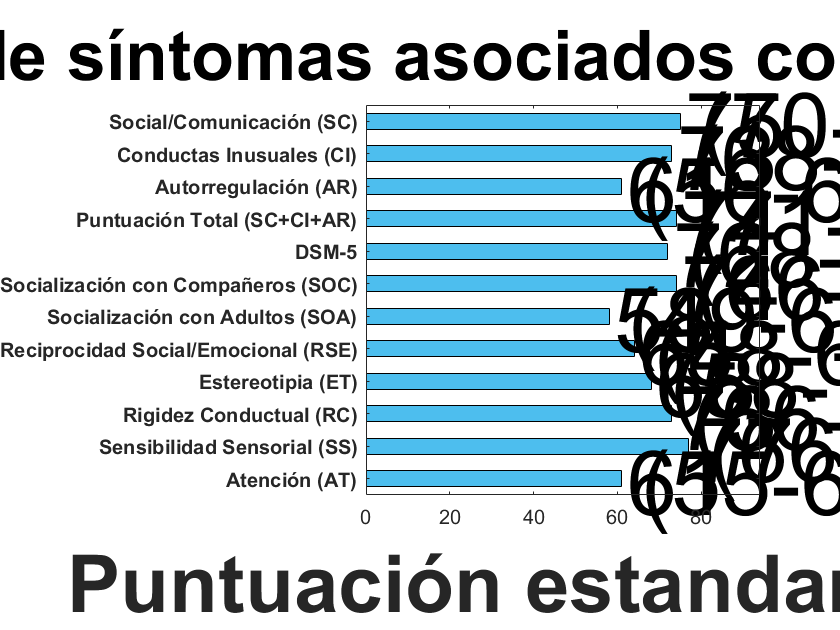

[WARN] ColumnSetup - No space remaining to distribute over columns.


%% Confidence Interval = 90%
clc; clear; close all;
MainPath = pwd; folder = MainPath; 
fileList = dir(fullfile(folder, '*.csv')); L = []; L=length(fileList);
n = cell(1,L); i = [];
for i = 1:1:L
   disp(['PARTICIPANT ' num2str(i)] )
   [filepath,name,ext] = fileparts([MainPath,'\',fileList(i).name]);
   n{1,i} = [name];
   data = []; data = readtable([name '.csv']);
   ratings = data;  CI = 90; file = name;
   % 1 for no speech or limited speech, 0 for fluent speech
   language = input("1 for no speech or limited speech, 0 for fluent speech: ");
   ASRS_Ratings_function_L(ratings,CI,file, language) 
end

PARTICIPANT 1


Social/Communication: prorated score for limited speech
Unusual Behaviours: prorated score for limited speech
Self Regulation: prorated score for limited speech
DSM-5: prorated score for limited speech
Peer Socialization: prorated score for limited speech
Adult Socialization: prorated score for limited speech
Social/Emotional Reprocitivity: prorated score for limited speech
Atypical Language: speech too limited to quantify
Stereotypy: no omitted response
Behavioural Rigidity: no omitted response
Sensory Sensitivity: no omitted response
Attention: no omitted response
6-11 years
Social Communication: Very Elevated
Unusual Behaviour: Very Elevated
Self-Regulation: Slightly Elevated
Total Score: Very Elevated
DSM-5: Very Elevated
Peer Socialization: Very Elevated
Adult Socialization: Average
Social/Emotional Reciprocity: Slightly Elevated
Atypical Language: speech too limited
Stereotypy: Elevated
Behavioural Rigidity: Very Elevated
Sensory Sensitivity: Very Elevated
Attention: Slightly Ele

6-11 years
Mejorar la capacidad de buscar a otros niños para socializar.
Mejorar las relaciones sociales con compañeros.
Aumentar el tiempo de juego con compañeros.
Mejorar la habilidad de entender y responder adecuadamente al humor.
Mejorar el juego interactivo con compañeros.
Mejorar la calidad de las interacciones con compañeros.
Mejorar la habilidad de responder adecuadamente al hablar con compañeros.
6-11 years
Mejorar las relaciones sociales con adultos.
6-11 years
Mejorar la habilidad de compartir experiencias agradables con otros.
Mejorar la habilidad de mirar a los demás al conversar con ellos.
Mejorar la habilidad de mirar a los demás cuando le hablan.
Mejorar la habilidad de apreciar y entender la opinión de los demás.
Mejorar la habilidad de entender los sentimientos y las emociones de los demás.
Mejorar la habilidad de reconocer adecuadamente señales sociales.
Desarrollar la habilidad de responder adecuadamente a las ideas y sentimientos de los demás.
Mejorar la habilidad 

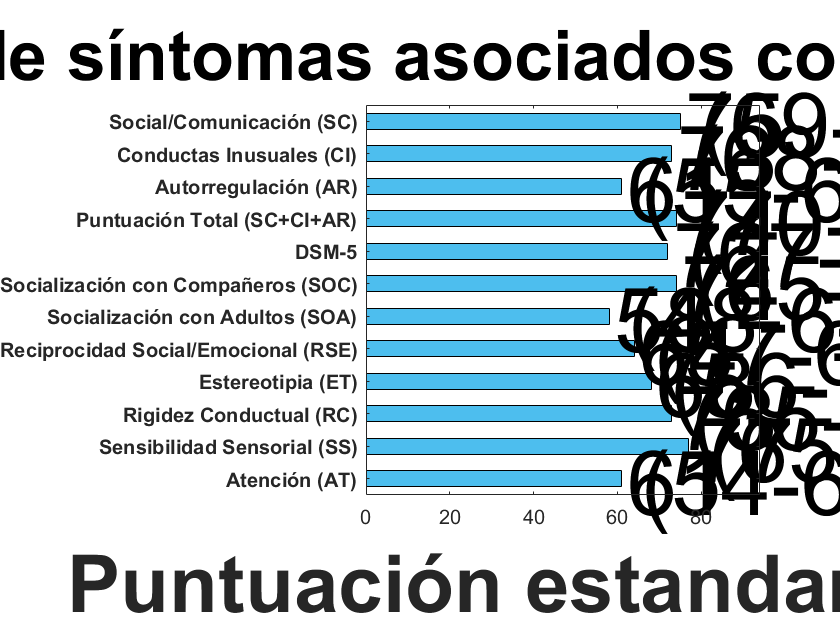

[WARN] ColumnSetup - No space remaining to distribute over columns.


%% Confidence Interval = 95%
clc; clear; close all;
MainPath = pwd; folder = MainPath; 
fileList = dir(fullfile(folder, '*.csv')); L = []; L=length(fileList);
n = cell(1,L); i = [];
for i = 1:1:L
   disp(['PARTICIPANT ' num2str(i)] )
   [filepath,name,ext] = fileparts([MainPath,'\',fileList(i).name]);
   n{1,i} = [name];
   data = []; data = readtable([name '.csv']);
   ratings = data;  CI = 95; file = name;
   % 1 for no speech or limited speech, 0 for fluent speech
   language = input("1 for no speech or limited speech, 0 for fluent speech: ");
   ASRS_Ratings_function_L(ratings,CI,file, language) 
end